# How macrophage-encoded bistable circuit generates tissue memory in concert with IECs

#### By Aditya, Tyler, Andrew 

In the colon tissue, we have intestinal epithelial cells (IECs) lining the colon, with macrophages interspersed below them. We found that inducing mild inflammation using a weaker dose of dextran sodium sulfate (DSS) in drinking water is protective against  a higher DSS challenge dose, akin to vaccination. We found that the mild inflammation greatly induces IL18 in colon tissue, most of which is derived from epithelium. We also found that macrophages are the ones that mediate the protection. Removing those "primed" macrophages thru clodronate liposomes failled to protect mice against the challenge DSS dose. So, in summary, the mild inflammation leads to an epithelial response (i.e. secretion of IL18) that influences the macrophages in the tissue and changes their metabolic state state to be protective. 

So, the question is what are the design principles in this colon tissue that allows for protection to happen? To be more specific, how is it that macrophages are able to generate and retain that memory, especially since IECs have a higher rate of renewal? 

## A macrophage-IEC circuit

We found that epithelium releases IL18, which activates the cGAS-cGAMP-STING pathway (IFN-beta is a downstream reporter of that pathway) in macrophages. Macrophages release cGAMP which then can activate IL18 activity in epithelium. This is in essence a positive feedback loop. Because of this positive feedback loop and the potential for a "tissue memory" to form, this can be a manifestation of a bistable circuit. Since tissues are communities of cells, this cross-talk of IL18/cGAMP among IECs/macrophages can just be one of many manifestations of a generalizable principle that tissues can utilize bistable circuits to encode memory.

## What is a bistable circuit? 

Bistability is a phenomenon when a system can exist in 2 stable states (e.g. ON or OFF). A hallmark aspect of bistability is that it relies on initial conditions or history of the system to inform which of the 2 stable states the system will occupy. A key feature of bistability is that it relies on positive feedback loops in order to generate an "ultrasensitive" response. We are studying how exposure to IL18 activates an intracellular process or transcription factor (TF) in macrophages that changes their cell state (i.e. ON or OFF).  See below where an intracellular TF $x$ is degraded linearly and produced at $\alpha \frac{x^n}{1+x^n}$, where $\alpha
$ is the maximal response and $n$ is the coefficient that controls the "ultrasensitivity" of the positive feedback loop. Greater the $n$, the stronger the positive the feedback loop such that it reaches the maximum value much quicker (i.e. the time to reach 1/2 max response is much quicker).

Below, we will examine how activity rate changes for different ultrasensitivity strengths ($n$ = 1,2,8) and different response strengths ($\alpha
$ = 1,2,3).

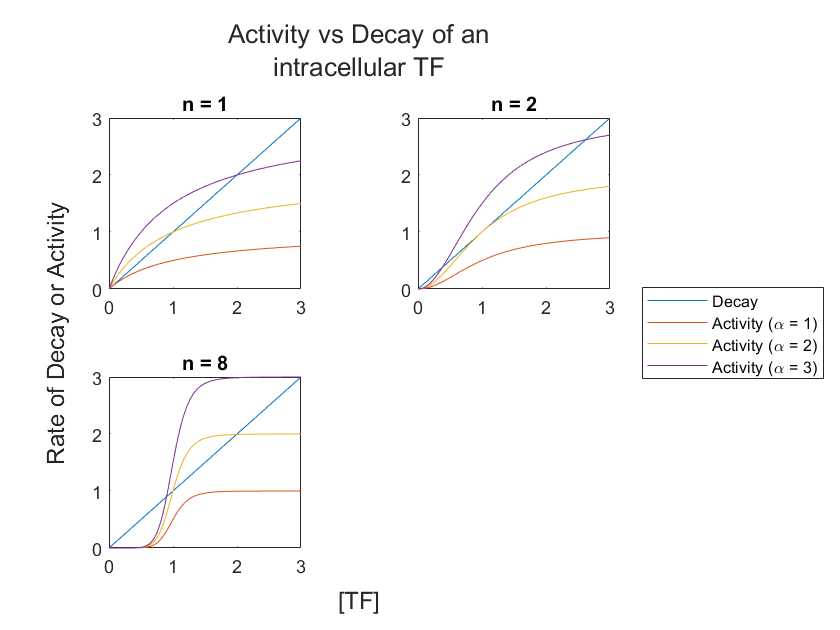

%% Illustrate activity vs decay
x = 0:0.01:3;
n_vals = [1, 2, 8];
alpha_vals = [1,2,3];

% define hill function
hill_func = @(x,alpha,n) alpha*(x.^n)./(1+x.^n);

% Make a subplot for each n value but differing alpha values

t=tiledlayout("flow");
xlabel(t,'[TF]');
ylabel(t,'Rate of Decay or Activity');
title(t,['Activity vs Decay of an',newline,'intracellular TF']);
for i=1:length(n_vals)
    n=n_vals(i);
%     figure();hold on;
    nexttile
    plot(x,x) % let decay rate be linear
    hold on;
    Legends={};
    Legends{1}='Decay';
    % plot activity rates
    for j=1:length(alpha_vals)
        alpha = alpha_vals(j);
        txt = ['Activity (\alpha = ',num2str(alpha),')'];
        y = hill_func(x,alpha,n);
        plot(x,y);
        Legends{1+j}=txt;
    end
    % set figure labels
    title(['n = ',num2str(n)])
    hold off
end

hl=legend(Legends);hl.Layout.Tile='East';
saveas(gcf,'plot0_activity_decay.jpg');

As you can see from the graphs, at low ultrasensitivity ($n$=1), the activity curves only intersect the decay curves twice (at 0 and another value). However, by increasing the ultrasensitivity (i.e. increasing $n$), the activity curve of the TF becomes more sigmoidal that is able to intersect with the decay curve 3 times (in the case of $n$=8 and $\alpha
$=3). This is super important! Wherever the activity curve intersects the decay is called a "fixed point", where the TF's activity and decay rates are equivalent and results in a steady-state. But how do these fixed points tell us how macrophages can reach their stable ON or OFF states? 

### How to characterize stability of the system using fixed points?

Let's take a look at the graph of the activity curve with $n$=8 and $\alpha
$=2 and find where they intersect with the decay curve. We can also set $n$=1 to mimic the hyperbolic Michaelis-Menten-like kinetics (MM-like).

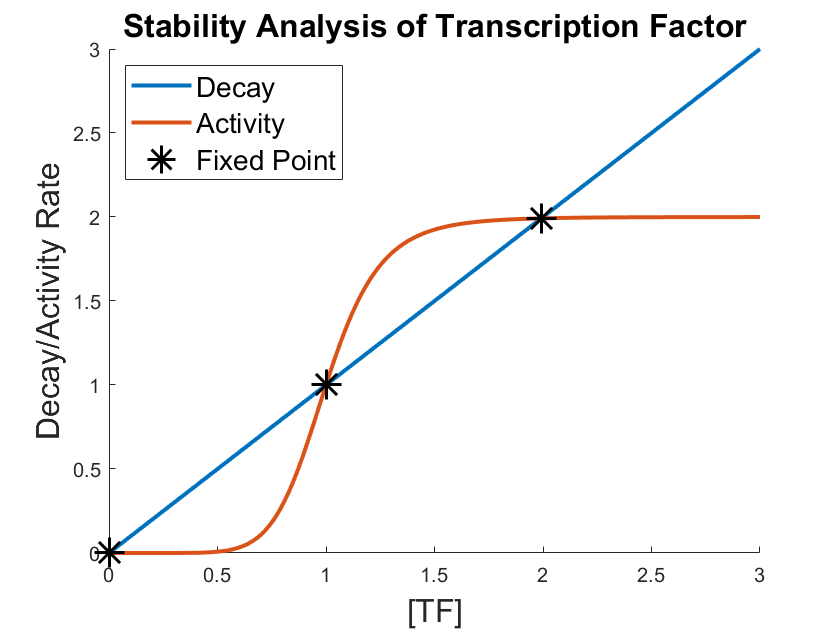

figure();hold on;
x = 0:0.01:3;n=8;alpha=2;
% Plot activity, decay curves
plot(x,x,'LineWidth',2) % let decay rate be linear
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y,'LineWidth',2);
Legends={};
Legends{1}='Decay';
Legends{2}='Activity';
xlabel('[TF]','FontSize',16)
ylabel('Decay/Activity Rate','FontSize',16)
title_txt = ['Stability Analysis of Transcription Factor'];
title(title_txt,'FontSize',16)

% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);

% plot the intersection points
hold on
plot(xout,yout,'k*','MarkerSize',15,'LineWidth',1.5)
Legends{3}='Fixed Point';
legend(Legends,'Location','northwest','FontSize',14)
saveas(gcf,'plot1_stabilityTF.jpg');

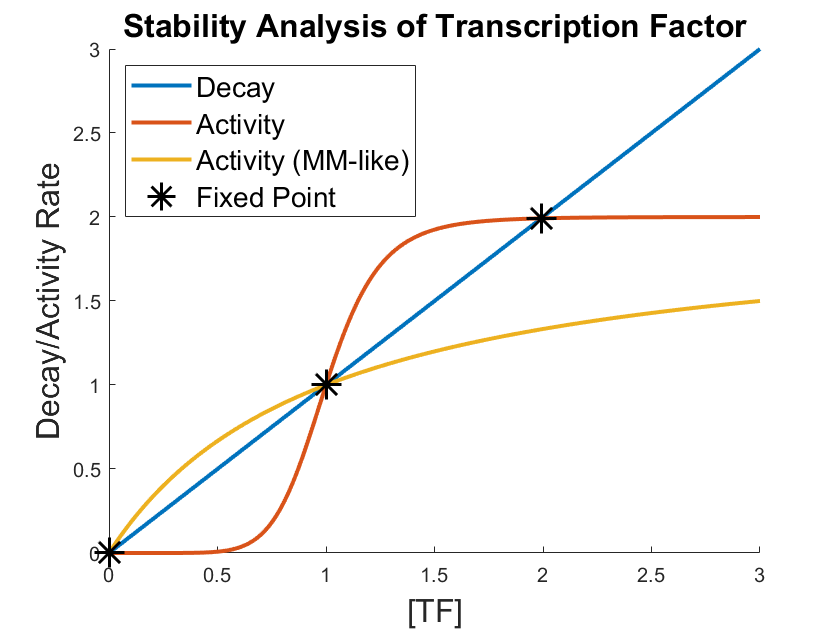

figure();hold on;
x = 0:0.01:3;n=8;alpha=2;
% Plot activity, decay curves
plot(x,x,'LineWidth',2) % let decay rate be linear
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y,'LineWidth',2); % n=8 curve
plot(x,hill_func(x,alpha,1),'LineWidth',2); % MM-like curve
Legends={};
Legends{1}='Decay';
Legends{2}='Activity';
Legends{3}='Activity (MM-like)';
xlabel('[TF]','FontSize',16)
ylabel('Decay/Activity Rate','FontSize',16)
title_txt = ['Stability Analysis of Transcription Factor'];
title(title_txt,'FontSize',16)

% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);
[xoutMM,youtMM] = intersections(x,x,x,hill_func(x,alpha,1),1);


% plot the intersection points
hold on
plot(xout,yout,'k*','MarkerSize',15,'LineWidth',1.5)
plot(xoutMM,youtMM,'k*','MarkerSize',15,'LineWidth',1.5)
Legends{4}='Fixed Point';
legend(Legends,'Location','northwest','FontSize',14)
saveas(gcf,'plot1_stabilityTF+MM.jpg');

We can see there are 3 intersections at [TF] (or x) = 0, 0.9, and 2. What is the behavior of our TF activity/decay system near these fixed points? We can use quiver plots to showcase the vector fields.

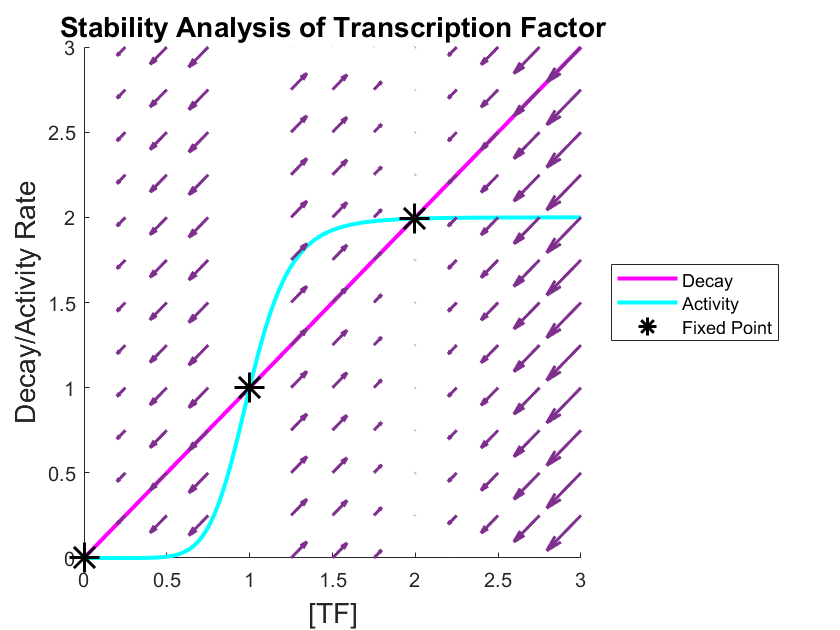

[xquiver,yquiver] = meshgrid(0:0.25:3);
rate = hill_func(xquiver,alpha,n)-xquiver;
u=rate;v=rate;

figure();hold on;
x = 0:0.01:3;n=8;alpha=2;
% Plot activity, decay curves
plot(x,x,'m','LineWidth',2) % let decay rate be linear
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y,'c','LineWidth',2);
Legends={};
Legends{1}='Decay';
Legends{2}='Activity';
xlabel('[TF]','FontSize',14)
ylabel('Decay/Activity Rate','FontSize',14)
title_txt = ['Stability Analysis of Transcription Factor'];
title(title_txt,'FontSize',14)

% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);

% plot the intersection points
hold on
plot(xout,yout,'k*','MarkerSize',15,'LineWidth',1.5);
Legends{3}='Fixed Point';

% plot quiver
hold on
h=quiver(xquiver,yquiver,u,v,'Linewidth',1.5);
legend(Legends,'Location','eastoutside');hold on;ylim([0,3]);
saveas(gcf,'plot2_stability+vector.jpg');

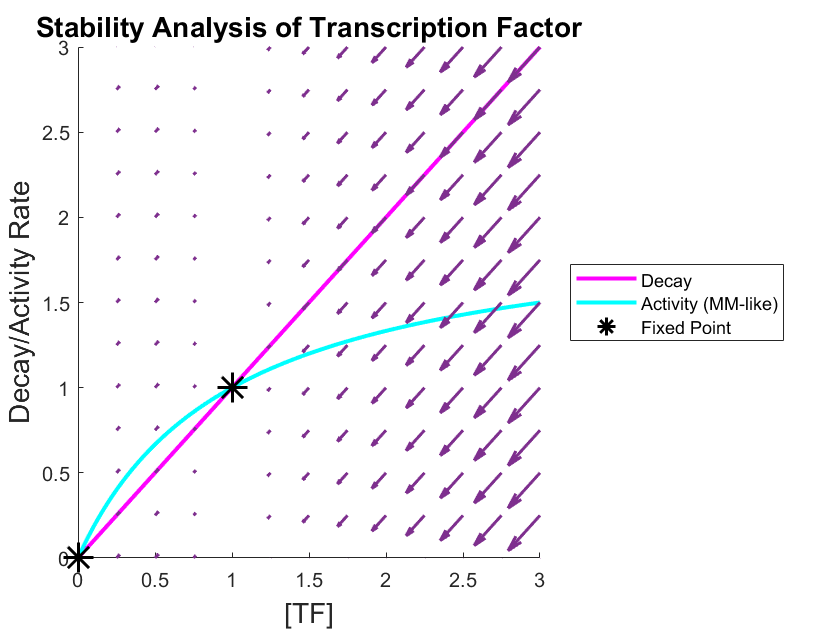

[xquiver,yquiver] = meshgrid(0:0.25:3);
rate = hill_func(xquiver,alpha,1)-xquiver;
u=rate;v=rate;

figure();hold on;
x = 0:0.01:3;n=8;alpha=2;
% Plot activity, decay curves
plot(x,x,'m','LineWidth',2) % let decay rate be linear
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,1);
plot(x,y,'c','LineWidth',2);
Legends={};
Legends{1}='Decay';
Legends{2}='Activity (MM-like)';
xlabel('[TF]','FontSize',14)
ylabel('Decay/Activity Rate','FontSize',14)
title_txt = ['Stability Analysis of Transcription Factor'];
title(title_txt,'FontSize',14)

% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,1),1);

% plot the intersection points
hold on
plot(xout,yout,'k*','MarkerSize',15,'LineWidth',1.5);
Legends{3}='Fixed Point';

% plot quiver
hold on
h=quiver(xquiver,yquiver,u,v,'Linewidth',1.5);
legend(Legends,'Location','eastoutside');hold on;ylim([0,3]);
saveas(gcf,'plot2_stability+vector_MM.jpg');

We can clearly see from our quiver plot that around the middle intersection ([TF]=1), the arrows are pointing to the left for the TF to go to 0 or to the right for the TF activity to go to 2. This means our middle intersection is an "unstable" fixed point whereas the left and right fixed points at [TF] = 0 (OFF), 2 (ON), respectively, are "stable" fixed points. So, if we are slightly to the right of the unstable fixed point, our TF will go to the ON position. If we are slightly to the left of the unstable fixed point, our TF will go to the OFF position. Similarly, if we go to the right of our stable "ON" fixed point ([TF]>2), our decay rate exceeds our activity rate, so we will return to that stable "ON" fixed point. All in summary, this means having an **ultrasensitive and strong enough positive feedback loop** can lead us to iterate between the stable ON and stable OFF states. But how do we transition from 1 steady-state fixed point to another?

### Switching between ON, OFF states

One of the most important things we need to understand is how we can switch between the OFF (0) steady-state to the ON (1) steady-state and vice versa. To switch from OFF to ON, we need to be able to pass a certain threshold of TF concentration in order to reach the ON state. This is typically seen in a dose escalation study where there is a sharp transition from an OFF state to an ON state. 

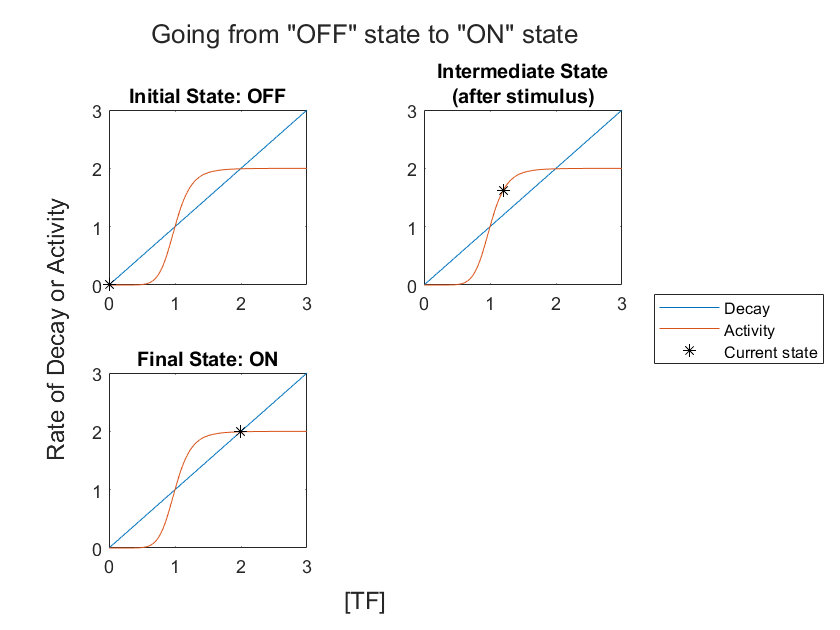

x = 0:0.01:3;n=8;alpha=2;
figure();
t=tiledlayout("flow");
xlabel(t,'[TF]')
ylabel(t,'Rate of Decay or Activity')
title_txt = 'Going from "OFF" state to "ON" state';
title(t,title_txt)

%% Initial state
nexttile
% Plot activity, decay curves
plot(x,x); % let decay rate be linear
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);
% plot the intersection points
hold on
plot(xout(1),yout(1),'k*')
title('Initial State: OFF')

%% Intermediate state
nexttile
% Plot activity, decay curves
plot(x,x); % let decay rate be linear
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);
% plot the intersection points
hold on
plot(1.2,hill_func(1.2,alpha,n),'k*')
title(['Intermediate State',newline,'(after stimulus)'])

%% Final state
nexttile
% Plot activity, decay curves
plot(x,x); % let decay rate be linear
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% plot the intersection points
hold on
plot(xout(3),yout(3),'k*')
title('Final State: ON')


Legends{1}='Decay';
Legends{2}='Activity';
Legends{3}='Current state';
hl=legend(Legends);
hl.Layout.Tile='East';
hold off
saveas(gcf,'plot2b_OFFtoON.jpg');

However, going from ON to OFF is more interesting. Basically, it requires us to make our decay rate exceed our activity rate (even transiently!). This can be accomplished by cell division, dilution, withdrawing of our stimulus that induces TF activity, etc. We can see the transition below for 2 cases, where we either increase decay rate or by withdrawing the stimulus:

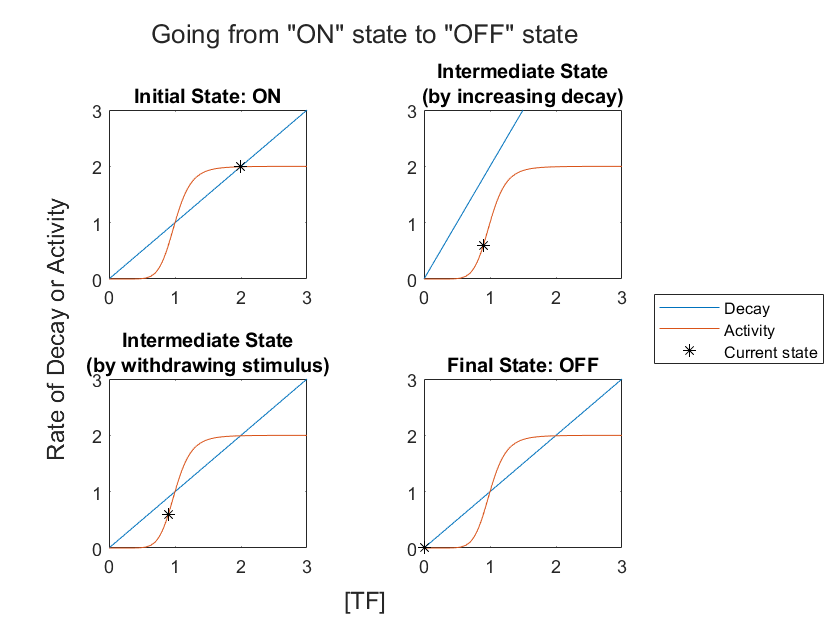

x = 0:0.01:3;n=8;alpha=2;

t=tiledlayout("flow");
xlabel(t,'[TF]')
ylabel(t,'Rate of Decay or Activity')
title_txt = ['Going from "ON" state to "OFF" state'];
title(t,title_txt)

%% Initial state
nexttile
% Plot activity, decay curves
plot(x,x); % let decay rate be linear
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);
% plot the intersection points
hold on
plot(xout(3),yout(3),'k*')
title('Initial State: ON')

%% Intermediate state
nexttile
% Plot activity, decay curves
plot(x,2*x); % let decay rate be linear
ylim([0 3])
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);
% plot the intersection points
hold on
plot(0.9,hill_func(0.9,alpha,n),'k*')
title(['Intermediate State',newline,'(by increasing decay)'])


%% Intermediate state
nexttile
% Plot activity, decay curves
plot(x,x); % let decay rate be linear
ylim([0 3])
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% Identify where the curves intersect
[xout,yout] = intersections(x,x,x,hill_func(x,alpha,n),1);
% plot the intersection points
hold on
plot(0.9,hill_func(0.9,alpha,n),'k*')
title(['Intermediate State',newline,'(by withdrawing stimulus)'])

%% Final state
nexttile
% Plot activity, decay curves
plot(x,x); % let decay rate be linear
hold on;
txt = ['Activity (\alpha = ',num2str(alpha),')'];
y = hill_func(x,alpha,n);
plot(x,y); 
% plot the intersection points
hold on
plot(xout(1),yout(1),'k*')
title('Final State: OFF')


Legends{1}='Decay';
Legends{2}='Activity';
Legends{3}='Current state';
hl=legend(Legends);hl.Layout.Tile='East';
saveas(gcf,'plot2c_ONtoOFF.jpg');

## Translating to an experimental system where we have to stimulate macrophages

Okay, so now we have an intuition for bistable systems and how we can switch between ON and OFF states. Let's translate this to our macrophage system. We have IECs that secrete IL18, which then impacts macrophages by signaling thru NCC, activating STING, and leading to IFN\beta expression. In addition, the STING activation leads to release of cGAMP from the macrophages, which in turn activates the IECs to secrete more IL18. So, since the macrophages are the ones that retain the protective memory due to IL18 stimulation, we shall focus on the macrophages and how they participiate in a bistable circuit.

Let's focus on the macrophages' ability to have a memory that may be enabled by a bistable circuit. Let's say that macrophages produce a TF or program that lets it retain the protective memory. So, we need to change our model a bit to account for the stimulus of IL18 that eventually activates that TF (which we can experimentally read out using IFN\beta). We will say that stimulus causes TF activity at rate $\beta$, so our transcription factor has the rate $$\frac{dx}{dt} = \beta + \alpha \frac{x^n}{1+x^n} - x$
$ with $\alpha$ being the positive feedback strength and $n$ controlling our ultrasensitivity. Let's take a look at how those trajectories look like:

tspan = 0:0.01:50;n=8;
% Base case: start with x0=0, alpha=2,beta=0.2
x0 = 0;alpha=1.2;beta=0.2;
[t,x1] = ode45(@(t,x) hill_func(x,alpha,n)+beta-x, tspan, x0);

% x0=0, alpha=2,beta=0.6
x0 = 0;alpha=1.2;beta=0.7;
[t,x3] = ode45(@(t,x) hill_func(x,alpha,n)+beta-x, tspan, x0);

% x0=1.6, alpha=2,beta=0.0
x0 = 1.6;alpha=1.2;beta=0.7;
[t,x4] = ode45(@(t,x) hill_func(x,alpha,n)+beta-x, tspan, x0);

% x0=1.6, alpha=2,beta=0.0
x0 = 1.6;alpha=0.6;beta=0.2;
[t,x2] = ode45(@(t,x) hill_func(x,alpha,n)+beta-x, tspan, x0);

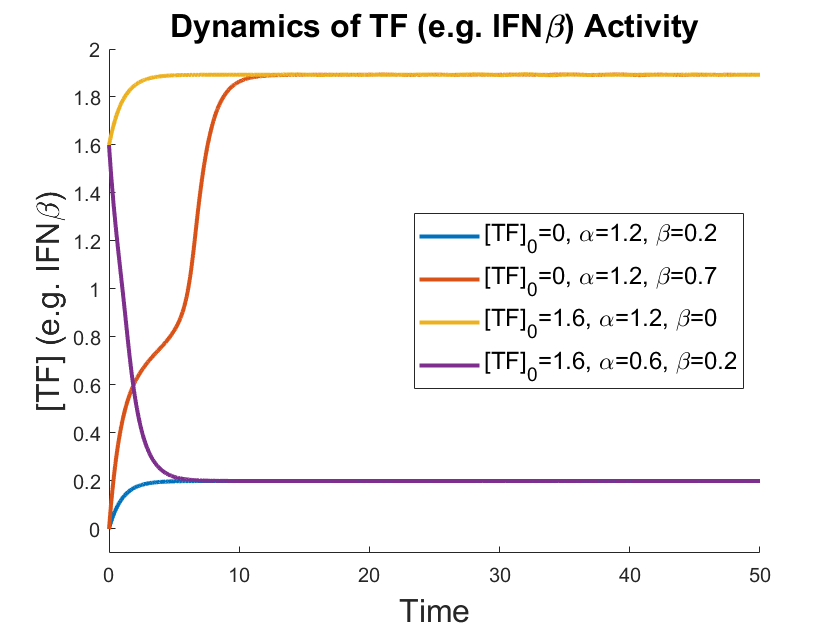

figure();hold on
plot(t,x1,'LineWidth',2);hold on;
plot(t,x3,'LineWidth',2);hold on;
plot(t,x4,'LineWidth',2);hold on;
plot(t,x2,'LineWidth',2);hold on;
xlabel('Time','FontSize',16);
ylabel('[TF] (e.g. IFN\beta)','FontSize',16);
Legends={};
Legends{1}='[TF]_0=0, \alpha=1.2, \beta=0.2';
Legends{2}='[TF]_0=0, \alpha=1.2, \beta=0.7';
Legends{3}='[TF]_0=1.6, \alpha=1.2, \beta=0';
Legends{4}='[TF]_0=1.6, \alpha=0.6, \beta=0.2';
legend(Legends,'Location','east','FontSize',12)
ylim([-0.1 2])
title('Dynamics of TF (e.g. IFN\beta) Activity','FontSize',16)
saveas(gcf,'plot3_TFdynamics.jpg');

As we can see from the above graph, there are 2 steady-state values: [TF]=0.2 (i.e. OFF) and [TF]=1.9 (i.e. ON). When we do not have any [TF] to start with ($[TF]_0$=0), $\beta$ induces the TF when it is sufficiently high (red curve, where $\beta$=0.7). However, if we do have some starting TF ($[TF]_0$=1.6), then our system is either 1) able to maintain TF expression in the absence of stimulus $\beta$ (yellow curve where $\beta$=0) or 2) decline to 0 if the feedback strength $\alpha
$ is lowered (purple curve where $\alpha
$ =0.6). The former case is akin to saying that our macrophages can stay ON even if there is no more IL18 stimulation.

### How does stimulus and positive feedback affect our ON/OFF steady-states?

Assuming that $n$=8, how do the stimulation and positive feedback strength (i.e. values of $\beta$ and $\alpha
$) influence our fixed points? We can accomplish by generating a phase diagram that shows the fixed points as a function of stimulus ($\beta$) and positive feedback strength ($\alpha
$).

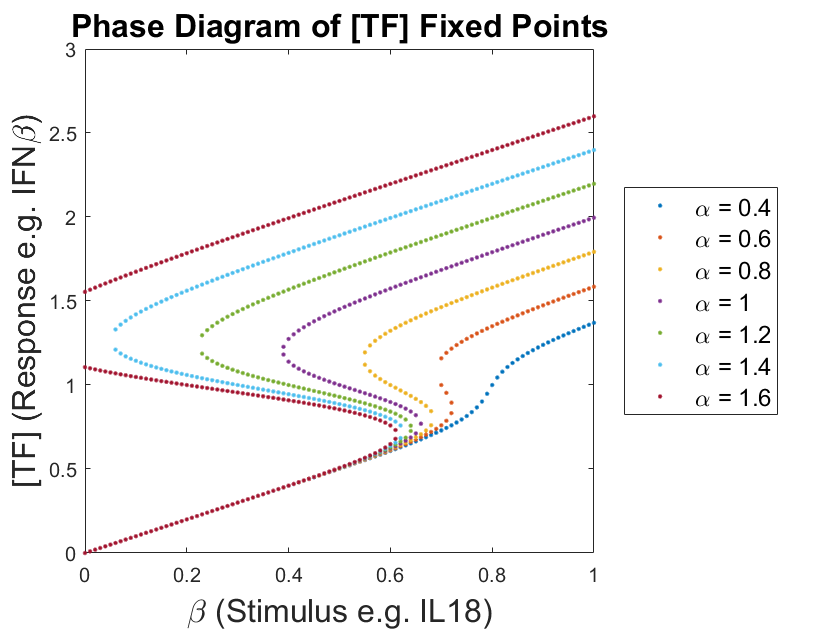

alpha_vals = 0.4:0.2:1.6;
beta_vals = 0:0.01:1;
n=8;
x = 0:0.01:3;

figure();Legends={};
for i=1:length(alpha_vals)
    alpha = alpha_vals(i);
%     disp(alpha);
    results_beta = [];
    results_x = [];
    for j=1:length(beta_vals)
        beta = beta_vals(j);
        % compute activity curve intersecting decay curve
        [xout,yout] = intersections(x,x,x,hill_func(x,alpha,n)+beta,1);
        results_x = cat(2,results_x, xout');
        results_beta = cat(2,results_beta, repmat(beta,1,size(xout,1)));
    end
    plot(results_beta,results_x,'.'); hold on;
    Legends{i}=['\alpha = ',num2str(alpha)];
end
legend(Legends,'Location','eastoutside','FontSize',12)
title('Phase Diagram of [TF] Fixed Points','FontSize',16)
xlabel('\beta (Stimulus e.g. IL18)','FontSize',16)
ylabel('[TF] (Response e.g. IFN\beta)','FontSize',16)
saveas(gcf,'plot4_PhaseDiagram.jpg');

We can see that at a given ultrasensitivity ($n$=8), increasing positive feedback strength $\alpha
$ allows us to have 3 fixed points at a a given stimulus $\beta$. One of the fixed points will be the unstable point discussed earlier while the other 2 are the stable steady-states at the OFF and ON positions.

### Positive feedback in a bistable system leads to hysteresis, a proxy for memory

Perhaps most importantly, we can see from the above graph that increasing the positive feedback strength $\alpha
$ leads to a greater range of stimulus $\beta$ that occupies an unstable fixed point, which can then subsequently transition to either the OFF or ON steady-states. That means there is more of a mismatch in the thresholds to go from OFF to ON and vice versa, i.e. the system exhibits hysteresis. This hysteresis can be a form of memory as it relies on the initial state of the macrophages and makes it more difficult to transition from one steady-state to another. 

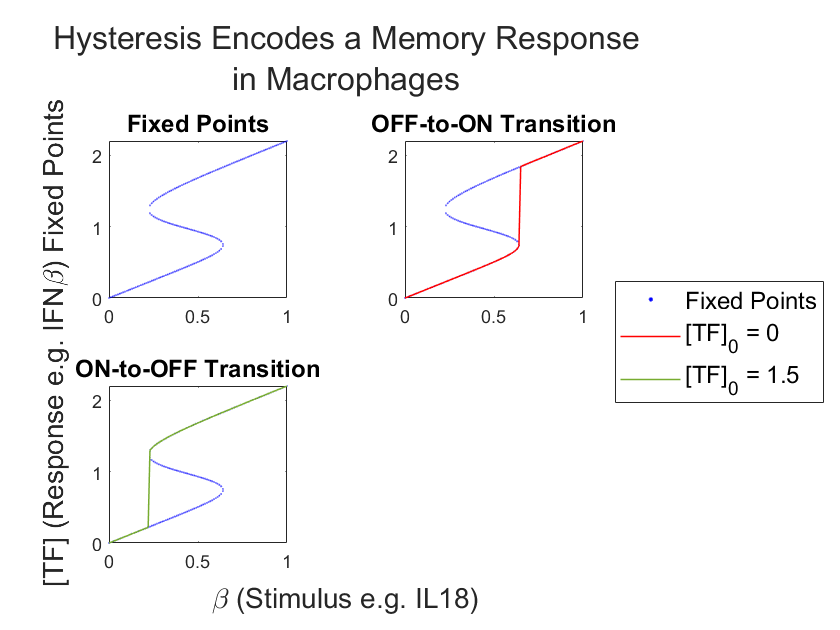

alpha=1.2;
n=8;
beta_vals = 0:0.01:1;
x = 0:0.01:3;
tspan = 0:0.01:50;

% Begin by plotting the fixed points
results_beta = [];
results_x = [];
for i=1:length(beta_vals)
    beta = beta_vals(i);
    % compute activity curve intersecting decay curve
    [xout,yout] = intersections(x,x,x,hill_func(x,alpha,n)+beta,1);
    results_x = cat(2,results_x, xout');
    results_beta = cat(2,results_beta, repmat(beta,1,size(xout,1)));
end


% Solve the ODE for [TF]0 = 0, 1.2
% start with x0=0
x0 = 0;
results_x1_ss = [];
for i=1:length(beta_vals)
    beta = beta_vals(i);
    [t,x1] = ode45(@(t,x) hill_func(x,alpha,n)+beta-x, tspan, x0);
    results_x1_ss = [results_x1_ss x1(end)];
end

% start with x0=1.2
x0_2 = 1.5;
results_x2_ss = [];
for i=1:length(beta_vals)
    beta = beta_vals(i);
    [t,x2] = ode45(@(t,x) hill_func(x,alpha,n)+beta-x, tspan, x0_2);
    results_x2_ss = [results_x2_ss x2(end)];
end

t=tiledlayout("flow");
nexttile;
plot(results_beta,results_x,'b.','MarkerSize',0.1);
title('Fixed Points','FontSize',12);

nexttile;
plot(results_beta,results_x,'b.','MarkerSize',0.1);hold on;
plot(beta_vals,results_x1_ss,'r','Linewidth',0.75);
title('OFF-to-ON Transition','FontSize',12);

nexttile;
plot(results_beta,results_x,'b.','MarkerSize',0.1);hold on;
plot(beta_vals,results_x2_ss,'g','color',"#77AC30",'Linewidth',0.75);
title('ON-to-OFF Transition','FontSize',12);

xlabel(t,'\beta (Stimulus e.g. IL18)','FontSize',14);
ylabel(t,'[TF] (Response e.g. IFN\beta) Fixed Points','FontSize',14);
title(t,['Hysteresis Encodes a Memory Response',newline, 'in Macrophages'],'FontSize',16);

% Create custom legend
qw{1} = plot(nan,'b.');
qw{2} = plot(nan,'r-','Linewidth',0.75);
qw{3} = plot(nan,'-','color',"#77AC30",'Linewidth',0.75);
hl=legend([qw{:}], {'Fixed Points', '[TF]_0 = 0','[TF]_0 = 1.5'},'FontSize',12);hl.Layout.Tile='East';

saveas(gcf,'plot5_HysteresisSchematic.jpg');

As you can see from the above graph, there is a mismatch in the thresholds of stimulus $\beta$ to turn ON and to turn OFF the macrophages. If the macrophages are initially OFF ($[TF]_0$=0), then they need more IL-18 (~0.6) to turn them ON. Conversely, if the macrophages are already ON  ($[TF]_0$=1.5), then they need much less IL-18 (~0.3) to turn them OFF. So, if we note a difference in these transition thresholds experimentally using IL18 as the stimulus and IFN\beta as the response signal, there is most likely evidence of the macrophages exhibiting bistable behavior.

## Examining experimental data 

### Characterize the OFF-to-ON transition and validate the ultrasensitivity assumption

We can read in actual data from the flow cytometry experiment and fit our activity curve to it.

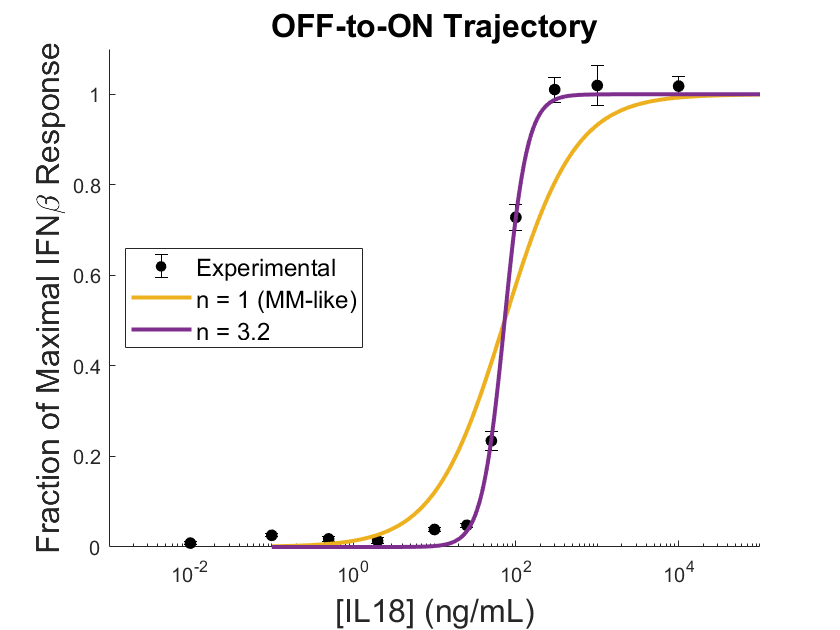

data_1 = readtable('20240130_Bistability_CompositeData_v2.csv');
% Plot mean +/- SEM of each dose. Using curve fitter, K=138.1, n=3.2 for
% OFF-to-ON. 

figure;hAx=axes;hAx.XScale='log';xlim([10^-3 100000]);ylim([0 1.1]);hold all;
% plot(data_1.IL18_ngmL,data_1.OFFtoON_Mean,'k.','MarkerSize',20); hold all;
errorbar(data_1.IL18_ngmL,data_1.OFFtoON_20230520_Mean, data_1.OFFtoON_20230520_SEM,'k.','MarkerSize',20)

x = 0:0.1:1e5;
K=72.7;
n_vals = [1,3.1];
color_list = ["#EDB120", "#7E2F8E"];
for i=1:length(n_vals)
    n=n_vals(i);
    semilogx(x,x.^n./(K^n+x.^n),'LineWidth',2,'color',color_list(i)); hold on;
end

xlabel('[IL18] (ng/mL)','FontSize',16);
ylabel('Fraction of Maximal IFN\beta Response','FontSize',16);
title('OFF-to-ON Trajectory','FontSize',16)
Legends={};
Legends{1}='Experimental';
Legends{2}='n = 1 (MM-like)';
Legends{3}='n = 3.2';
legend(Legends,'Location','west','FontSize',12);
saveas(gcf,'plot6_HillFit.jpg');

We want to show that our experimental data does not fit Michaelis-Menten type kinetics ("MM-like") that can be approximated with a Hill coefficient $\frac{x^n}{K^n+x^n}$, but with $n$=1 (MM-like, yellow curve). Using curve fitter, we found K = 138.1, and n = 3.2. This demonstrates that the BMDM's IFN\beta response to IL18 stimulation is ultrasensitive/cooperative as it does not fit the hyperbolic behavior expected from Michaelis-Menten like responses.

### Characterize the decay of IFN\beta signaling after withdrawing IL18 stimulus and validate it fits an exponential decay

We need to validate that the IL18 stimulation does not induce a durable IFN\beta response in BMDMs (i.e. it induces reversible IFN\beta response) for the time scale we are considering. As a result, BMDMs were stimulated with IL18 for 2 days, withdrawn, and then IFN\beta signaling was measured over a time course of 4 days after the IL18 withdrawal.

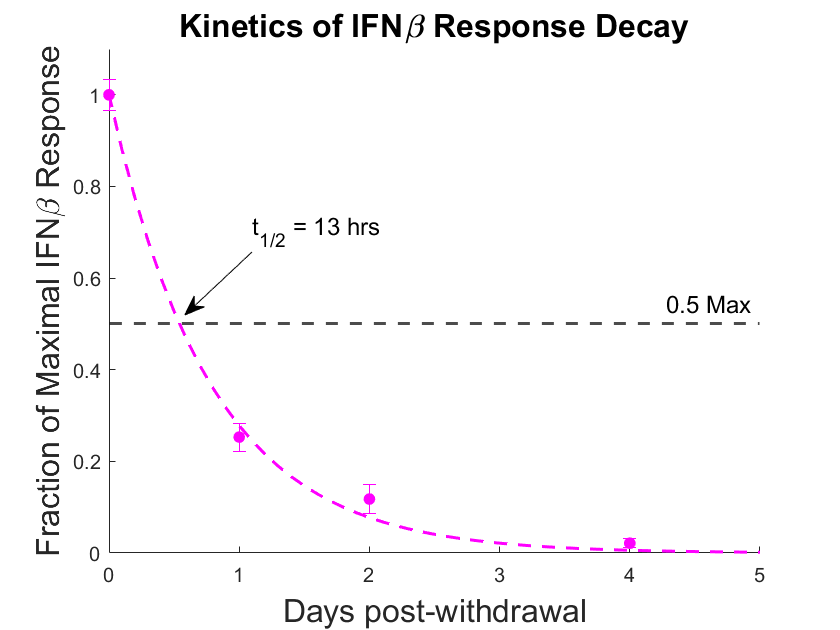

% Plot mean +/- SEM of each day's response. Using curve fitter of
% exponential a*exp(b*x), a=0.9967 (rounding to 1), b=-1.28
data_2=readtable('TM_timeDecay.csv');
% set axes limits
x = 0:0.1:5;
figure;xlim([0 5]);ylim([0 1.1]);hold all;
% Plot mean +/- SEM
errorbar(data_2.Days,data_2.Mean, data_2.SEM,'m.','MarkerSize',20);
% plot fit curve
b=-1.28;
plot(x,exp(b.*x),'m--','LineWidth',1.5,'HandleVisibility','off');

% Plot the 50% line
yline(0.5,'k--','0.5 Max','LineWidth',1.5,'FontSize',12)
x1=[0.30 0.22];y1=[0.6 0.5]; annotation('textarrow',x1,y1,'String','t_{1/2} = 13 hrs','FontSize',12);

xlabel('Days post-withdrawal','FontSize',16);
ylabel('Fraction of Maximal IFN\beta Response','FontSize',16);
title('Kinetics of IFN\beta Response Decay','FontSize',16);
saveas(gcf,'plot7_IFNbDecay.jpg');

### Characterize the ON-to-OFF transition and the memory-via-hysteresis

We want to see the mismatch in IL18 requirements (i.e. hysteresis) between turning ON the IFNb response in naive ("OFF") BMDMs and turning OFF the IFNb response in activated ("ON") BMDMs. The results are below and curves were fit to the Hill equation.

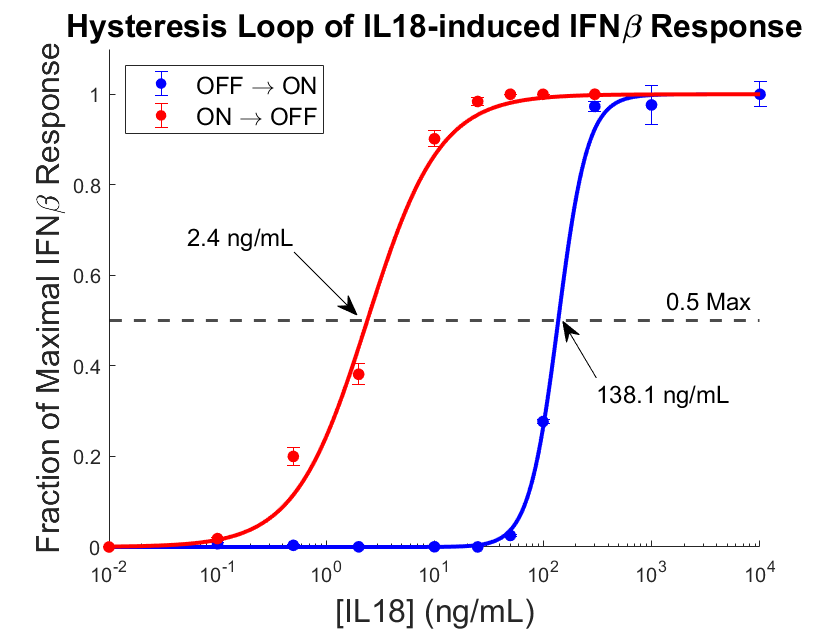

% Plot mean +/- SEM of each dose. Using curve fitter, K=138.1, n=3.2 for
% OFF-to-ON. 
% Set axes limits
x = 0:0.01:1e5;
figure;hAx=axes;hAx.XScale='log';xlim([10^-2 10000]);ylim([0 1.1]);hold all;

% Plot OFF-to-ON experimental data and the fitted curve
errorbar(data_1.IL18_ngmL,data_1.OFFtoON_20230422_Mean, data_1.OFFtoON_20230422_SEM,'b.','MarkerSize',20);
K_OFFtoON=138.1;
n_OFFtoON=3.2;
plot(x,x.^n_OFFtoON./(K_OFFtoON^n_OFFtoON+x.^n_OFFtoON),'b','LineWidth',2,'HandleVisibility','off'); hold on;

% Plot ON-to-OFF experimental data and the fitted curve
errorbar(data_1.IL18_ngmL,data_1.ONtoOFF_20230422_Mean, data_1.ONtoOFF_20230422_SEM,'r.','MarkerSize',20);
K_ONtoOFF=2.40;
n_ONtoOFF=1.3;
plot(x,x.^n_ONtoOFF./(K_ONtoOFF^n_ONtoOFF+x.^n_ONtoOFF),'r','LineWidth',2,'HandleVisibility','off'); hold on;

% Plot the 50% line
yline(0.5,'k--','0.5 Max','LineWidth',1.5,'FontSize',12)
x1=[0.35 0.425];x2=[0.6 0.5]; annotation('textarrow',x1,x2,'String','2.4 ng/mL','FontSize',12);
x3=[0.71 0.67];x4=[0.4 0.49]; annotation('textarrow',x3,x4,'String','138.1 ng/mL','FontSize',12);


xlabel('[IL18] (ng/mL)','FontSize',16);
ylabel('Fraction of Maximal IFN\beta Response','FontSize',16);
title('Hysteresis Loop of IL18-induced IFN\beta Response','FontSize',16)
Legends={};
Legends{1}='OFF \rightarrow ON';
Legends{2}='ON \rightarrow OFF';
legend(Legends,'Location','northwest','FontSize',12);
saveas(gcf,'plot8_IFNbHysteresis.jpg');

Whereas the OFF-to-ON trajectory had K=138.1 ng/mL and n=3.2, the ON-to-OFF trajectory had K=2.4 ng/mL and n=1.3. As K represents the IL18 concentration needed to reach half of the maximal response value, we can see that the hysteresis loop spans a 58-fold difference between these K values.

### Characterize what intracellular signaling is required for the memory-via-hysteresis

This hysteresis in the IL18-IFNb axis in BMDMs must be relying on some intracellular processes, so we wanted to identify which ones. We hypothesized that NCC signaling and fatty acid oxidation may play a role in maintaining this hysteresis. So, we pretreated BMDMs with IL18 to turn them ON, and then we gave BMDMs an inhibitor against NCC (NCCi) or an inhibitor against PPARa (PPARi), which is a transcription factor that drives fatty acid oxidation. Then, the IFNb response was measured after the treatment with inhibitors. We would expect that the inhibitors would cause IFNb treatment to be between the ON-to-OFF trajectory (because that would mean that hysteresis is fully maintained, so it is the upper bound), or the OFF-to-ON trajectory (because the inhibitors would totally abolish the hysteresis effect, so it would be the lower bound).

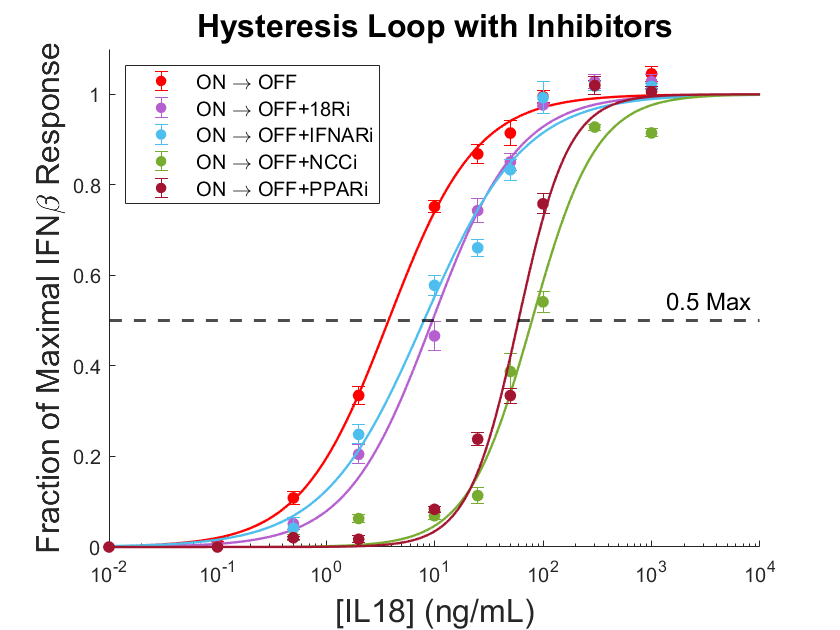

% Plot mean +/- SEM of each dose. Using curve fitter, K=138.1, n=3.2 for
% OFF-to-ON. 
% Set axes limits
x = 0:0.01:1e5;
figure;hAx=axes;hAx.XScale='log';xlim([10^-2 10000]);hold all;


% Plot ON-to-OFF experimental data and the fitted curve
errorbar(data_1.IL18_ngmL,data_1.ONtoOFF_20230520_Mean, data_1.ONtoOFF_20230520_SEM,'r.','MarkerSize',20);
K_ONtoOFF=3.76;
n_ONtoOFF=1.07;
plot(x,x.^n_ONtoOFF./(K_ONtoOFF^n_ONtoOFF+x.^n_ONtoOFF),'r','LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot the 50% line
yline(0.5,'k--','0.5 Max','LineWidth',1.5,'FontSize',12,'HandleVisibility','off')

% Plot 18R experimental data 
errorbar(data_1.IL18_ngmL,data_1.R18_Mean, data_1.R18_SEM,'.','color','#b65fcf','MarkerSize',20);
k_18R = 9.56;n_18R = 1.09;
plot(x,x.^n_18R./(k_18R^n_18R+x.^n_18R),'color','#b65fcf','LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot IFNARi experimental data 
% read in data
data_4 = readtable('20240130_Bistability_CompositeData_v2.csv');
errorbar(data_4.IL18_ngmL,data_4.IFNARi_Mean, data_4.IFNARi_SEM,'.','color','#4DBEEE','MarkerSize',20);
k_IFNARi = 7.985;n_IFNARi = 0.9394;
plot(x,x.^n_IFNARi./(k_IFNARi^n_IFNARi+x.^n_IFNARi),'color','#4DBEEE','LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot NCCi experimental data 
errorbar(data_1.IL18_ngmL,data_1.ncci_Mean, data_1.ncci_SEM,'.','color',"#77AC30",'MarkerSize',20);
k_ncc = 78.96;n_ncc = 1.46;
plot(x,x.^n_ncc./(k_ncc^n_ncc+x.^n_ncc),'color',"#77AC30",'LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot PPARi experimental data 
errorbar(data_1.IL18_ngmL,data_1.ppari_Mean, data_1.ppari_SEM,'.','color',"#A2142F",'MarkerSize',20);
k_ppar = 59.35;n_ppar = 1.871;
plot(x,x.^n_ppar./(k_ppar^n_ppar+x.^n_ppar),'color',"#A2142F",'LineWidth',1.2,'HandleVisibility','off'); hold on;



% label
xlabel('[IL18] (ng/mL)','FontSize',16);
ylabel('Fraction of Maximal IFN\beta Response','FontSize',16);
title('Hysteresis Loop with Inhibitors','FontSize',16)
Legends={};
Legends{1}='ON \rightarrow OFF';
Legends{2}='ON \rightarrow OFF+18Ri';
Legends{3}='ON \rightarrow OFF+IFNARi';
Legends{4}='ON \rightarrow OFF+NCCi';
Legends{5}='ON \rightarrow OFF+PPARi';

set(gca, 'ylim',[0 1.1]);
set(gca, 'ytick',[0:0.2:1.0]);

legend(Legends,'Location','northwest','FontSize',10);
saveas(gcf,'plot9_IFNbHysteresis+Inhibitors.jpg');

As we can see from the above graph, BMDMs that received treatment of NCCi or PPARi had a greatly diminished IFNb response with a 0.5 Max value at approximately 35 ng/mL, indicating that NCC signaling and fatty acid oxidation are processes required for BMDMs to maintain their IFNb response after IL18 stimulation.

## The IL-18-cGAMP circuit is oscillatory in nature

How can macrophages maintain the activity of the bistable program? We hypothesized that it may be due to oscillations of IL-18 in the environment. Indeed, that is what we have found.

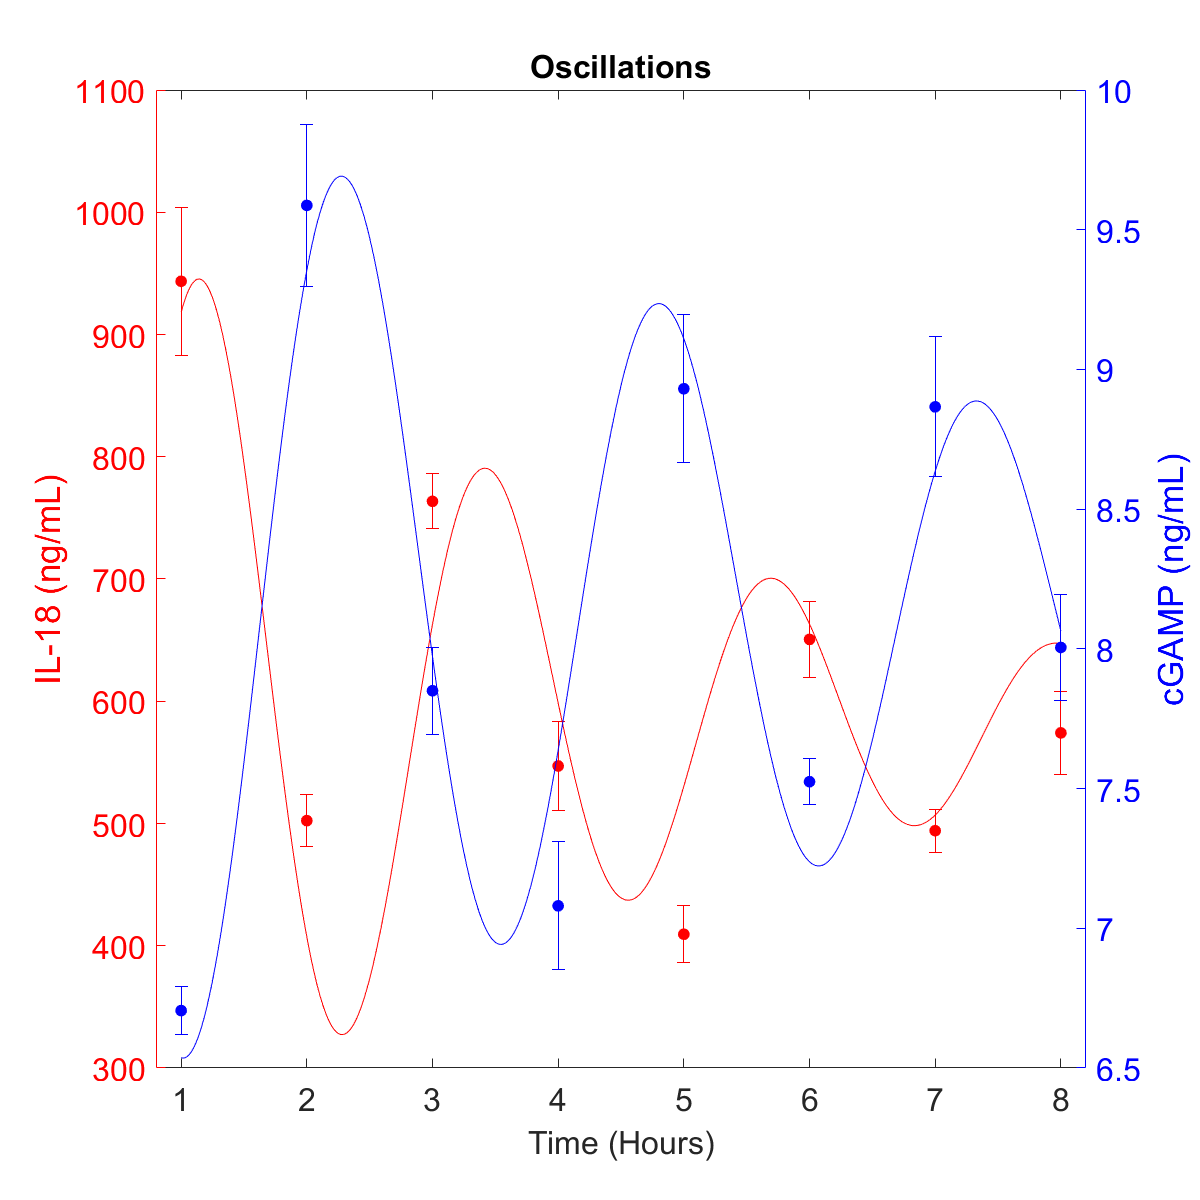

% Import oscillation data
data_3 = readtable('TM_oscillationDataMatlab.csv');
% specify number of timepoints to analyze/plot
num_tmpts = 8;
% num_tmpts = size(data_3,1);

% Plot the data points in 8 hours
figure('Position',[0 0 800 800]);
yyaxis left
errorbar(data_3.TimeHours(1:num_tmpts),data_3.Mean_IL18(1:num_tmpts),...
    data_3.SEM_IL18(1:num_tmpts),'r.','MarkerSize',20);hold on;
% Plot curvefits
x=1:0.01:8;
a1=464.8;a2=47.19;b1=0.2468;b2=2.761;c=-1.748;d=596.4;
curve_IL18 = d-a1*exp(-b1.*x).*cos(b2.*x)-a2*exp(-b1.*x).*sin(b2.*x)+c.*x;
plot(x,curve_IL18,'r-'); hold on;ylabel('IL-18 (ng/mL)','FontSize',16)

yyaxis right
errorbar(data_3.TimeHours(1:num_tmpts),data_3.Mean_cGAMP(1:num_tmpts),...
    data_3.SEM_cGAMP(1:num_tmpts),'b.','MarkerSize',20); hold on;
a1=-1.6418;a2=1.0573;b1=0.125;b2=2.4858;c=-0.0232;d=8.2773;
curve_cGAMP = d-a1*exp(-b1.*x).*cos(b2.*x)-a2*exp(-b1.*x).*sin(b2.*x)+c.*x;
plot(x,curve_cGAMP,'b-');ylabel('cGAMP (ng/mL)','FontSize',16)
ax=gca;
ax.FontSize=16;
ax.YAxis(1).Color='r';ax.YAxis(2).Color='b';

% label
xlabel('Time (Hours)','FontSize',16);xlim([.8 8.2])
title('Oscillations','FontSize',16);
saveas(gcf,'plot10_cGAMP-IL18-Oscillations.jpg');

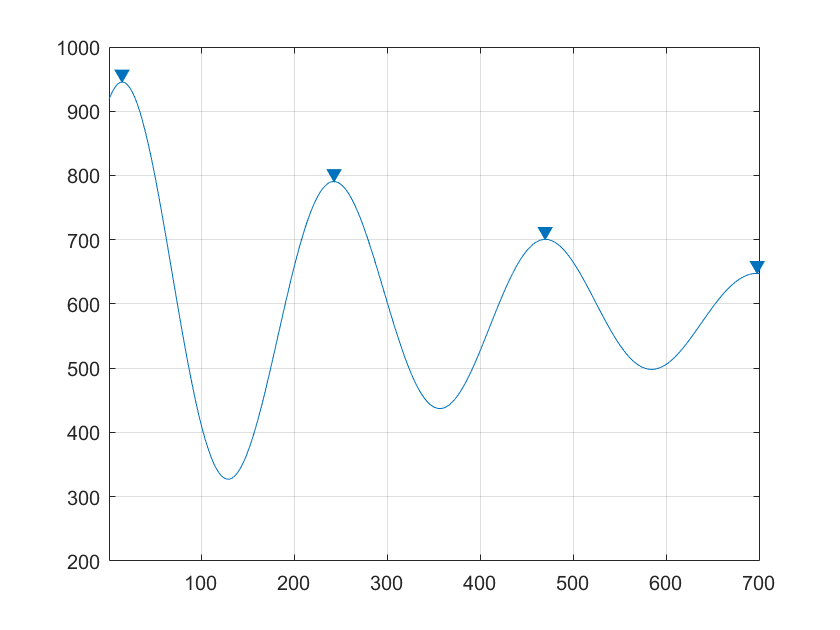

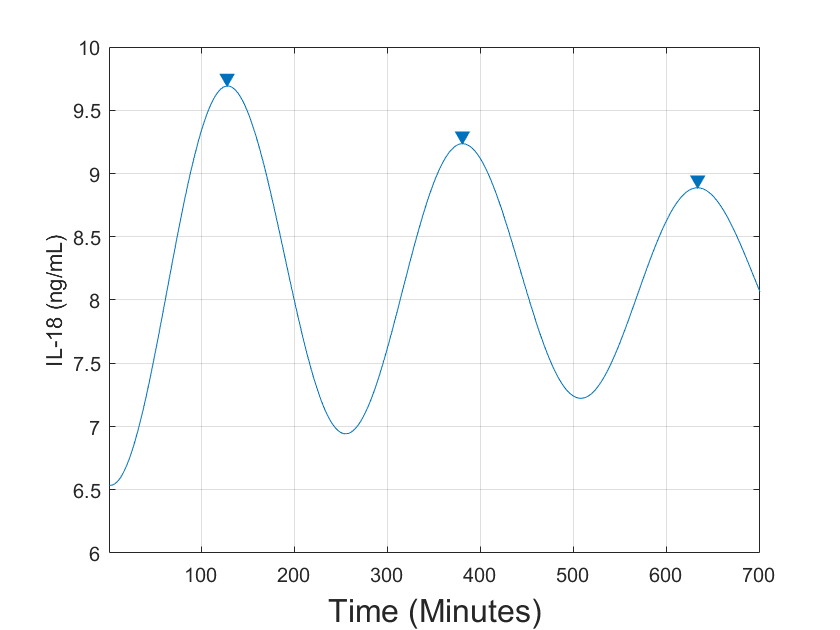

% Find index of peaks and associated time delays (i.e. phase difference) between the
% signals
[~,pks_IL18] = findpeaks(curve_IL18);[~,pks_cGAMP] = findpeaks(curve_cGAMP);
figure;title('IL-18 levels');xlabel('Time (Minutes)','FontSize',16);ylabel('IL-18 (ng/mL)');
findpeaks(curve_IL18);figure; findpeaks(curve_cGAMP);xlabel('Time (Minutes)','FontSize',16);ylabel('IL-18 (ng/mL)');

% find timepoints of each peak
timePks_IL18 = x(pks_IL18);timePks_cGAMP = x(pks_cGAMP);
% Now find the difference from IL18 peak to cGAMP peaks
PhaseDiff = timePks_cGAMP - timePks_IL18(1:length(timePks_cGAMP));
% Find the peak-to-peak (i.e. period) for each signal
Period_IL18 = diff(timePks_IL18);
Period_cGAMP = diff(timePks_cGAMP);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Next calculate the sum of squares error and sum of squares total
timePts = [1 2 3 4 5 6 7 8];
% get indices where the x is equal to the timepts
idx_timePts = find(ismember(x, timePts));
% now perform Rsquared calculation
R2_IL18 = rsquare(data_3.Mean_IL18(1:num_tmpts), curve_IL18(idx_timePts));
R2_cGAMP = rsquare(data_3.Mean_cGAMP(1:num_tmpts), curve_cGAMP(idx_timePts));

The rsquare values of the IL18 and cGAMP curves are 0.78 and 0.91, respectively. We also find that their periods of the IL18 and cGAMP curve fits are 2.28 and 2.53 hours, respectively. The lag-time between the curves is ~1.4 hours. 

## Probing role of IFNb and IFNAr signaling on hysteresis

We have now established that IL18 stimulation launches an intracellular bistable circuit in macrophages through mitochondrial fatty acid oxidation and cGAMP signaling. However, a confounding circuit is IFNa and IFNb signaling as both can potentially induce FAO. Let's first show whether the hysteresis from the IL18-induced circuit relies on IFNa signaling by giving an anatagonist (IFNARi) against the IFNa receptor IFNAR.

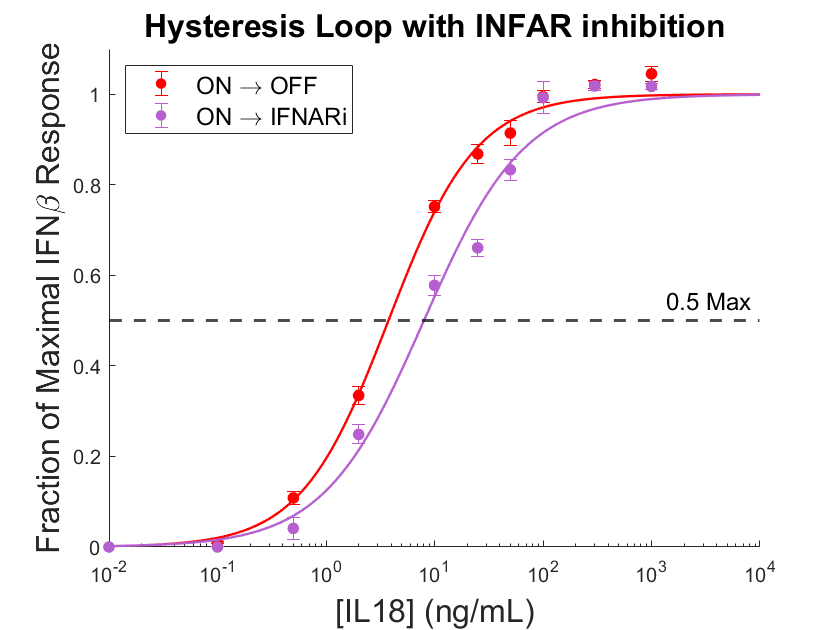

% read in data
data_4 = readtable('20240130_Bistability_CompositeData_v2.csv');

% Plot mean +/- SEM of each dose. Using curve fitter, K=138.1, n=3.2 for
% OFF-to-ON. 
% Set axes limits
x = 0:0.01:1e5;
figure;hAx=axes;hAx.XScale='log';xlim([10^-2 10000]);hold all;


% Plot ON-to-OFF experimental data and the fitted curve
errorbar(data_4.IL18_ngmL,data_4.ONtoOFF_20230520_Mean, data_4.ONtoOFF_20230520_SEM,'r.','MarkerSize',20);
K_ONtoOFF=3.76;
n_ONtoOFF=1.07;
plot(x,x.^n_ONtoOFF./(K_ONtoOFF^n_ONtoOFF+x.^n_ONtoOFF),'r','LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot the 50% line
yline(0.5,'k--','0.5 Max','LineWidth',1.5,'FontSize',12,'HandleVisibility','off')

% Plot IFNARi experimental data 
errorbar(data_4.IL18_ngmL,data_4.IFNARi_Mean, data_4.IFNARi_SEM,'.','color','#b65fcf','MarkerSize',20);
k_IFNARi = 7.985;n_IFNARi = 0.9394;
plot(x,x.^n_IFNARi./(k_IFNARi^n_IFNARi+x.^n_IFNARi),'color','#b65fcf','LineWidth',1.2,'HandleVisibility','off'); hold on;
Legends={};
Legends{1}='ON \rightarrow OFF';
Legends{2}='ON \rightarrow IFNARi';
legend(Legends,'Location','northwest','FontSize',12);

xlabel('[IL18] (ng/mL)','FontSize',16);
ylabel('Fraction of Maximal IFN\beta Response','FontSize',16);
title('Hysteresis Loop with INFAR inhibition','FontSize',16);

set(gca, 'ylim',[0 1.1]);
set(gca, 'ytick',[0:0.2:1.0]);

saveas(gcf,'plot11_IFNARi-hysteresis.jpg');

So we can see here that the IFNAR signaling is rather dispensable for the hysteresis exhibited by IL18's circuit. Now, can IFNb make a similar circuit?

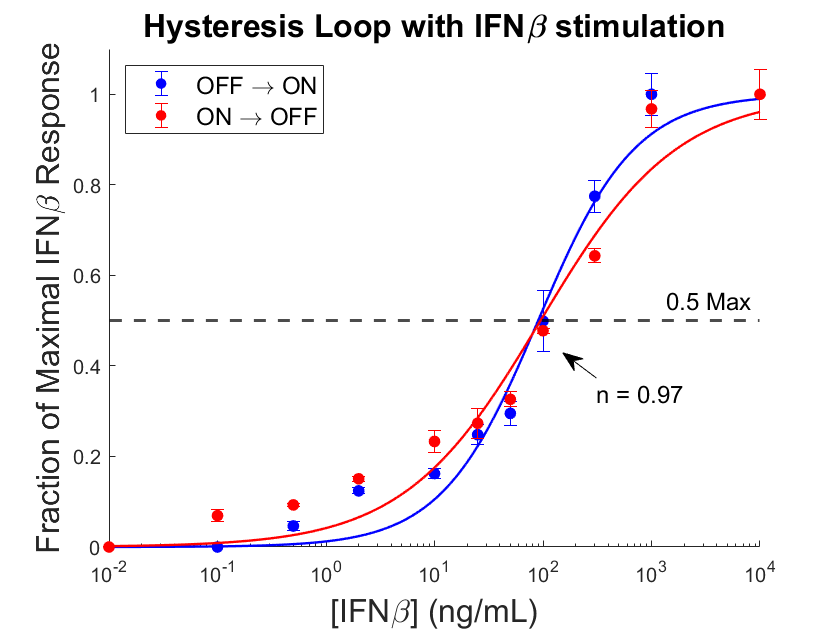

% Plot mean +/- SEM of each dose. Using curve fitter, K=138.1, n=3.2 for
% OFF-to-ON. 
% Set axes limits
x = 0:0.01:1e5;
figure;hAx=axes;hAx.XScale='log';xlim([10^-2 10000]);hold all;

% Plot OFF-to-ON experimental data and the fitted curve
errorbar(data_4.IFNb_ngmL,data_4.ifnb_OFFtoON_Mean,data_4.ifnb_OFFtoON_SEM,'b.','MarkerSize',20);
K_OFFtoON=90.1938;
n_OFFtoON=0.9733;
plot(x,x.^n_OFFtoON./(K_OFFtoON^n_OFFtoON+x.^n_OFFtoON),'b','LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot ON-to-OFF experimental data and the fitted curve
errorbar(data_4.IFNb_ngmL,data_4.ifnb_ONtoOFF_Mean,data_4.ifnb_ONtoOFF_SEM,'r.','MarkerSize',20);
K_ONtoOFF=94.8368;
n_ONtoOFF=0.6881;
plot(x,x.^n_ONtoOFF./(K_ONtoOFF^n_ONtoOFF+x.^n_ONtoOFF),'r','LineWidth',1.2,'HandleVisibility','off'); hold on;

% Plot the 50% line
yline(0.5,'k--','0.5 Max','LineWidth',1.5,'FontSize',12,'HandleVisibility','off')

Legends={};
Legends{1}='OFF \rightarrow ON';
Legends{2}='ON \rightarrow OFF';
legend(Legends,'Location','northwest','FontSize',12);
xlabel('[IFN\beta] (ng/mL)','FontSize',16);
ylabel('Fraction of Maximal IFN\beta Response','FontSize',16);
title('Hysteresis Loop with IFN\beta stimulation','FontSize',16);
x3=[0.71 0.67];x4=[0.4 0.44]; annotation('textarrow',x3,x4,'String','n = 0.97','FontSize',12);
set(gca, 'ylim',[0 1.1]);
set(gca, 'ytick',[0:0.2:1.0]);

saveas(gcf,'plot12_IFNb-hysteresis.jpg');

So, we can see here that although IFNb stimulation does lead to elevated FAO (as seen with the increase in IFNb reporter signal), there is no hysteresis when IFNb is withdrawn. This is markedly different behavior in contrast to the hysteresis seen with IL18 stimulation, which implies that the IL18-induced circuit operates through a different feedback mechanism than the one used by IFNb stimulation.

## Effect of cGAMP, IFNb on maximal OCR

We found that cGAMP increases maximal OCR while IFNb decreases it on BMDMs. 

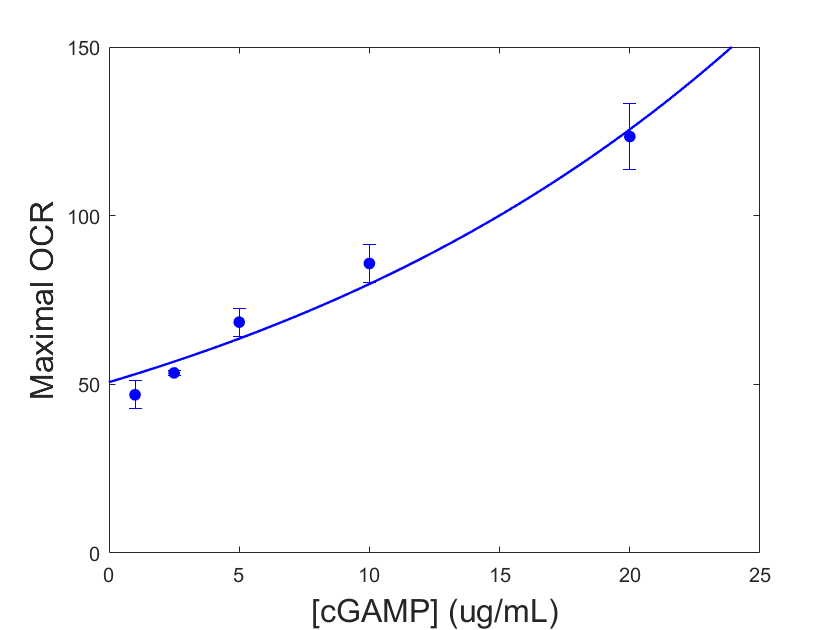

data_5 = readtable('20240216_MaxOCR-cGAMP+IFNb.csv');
% Plot figure of cGAMP
x = 0:0.1:25;
% t=tiledlayout(1,2);
% Plot experimental data and the fitted curve
% nexttile;
figure;
errorbar(data_5.cGAMP_ugMl, data_5.cGAMP_Mean, data_5.cGAMP_SEM,'b.','MarkerSize',20);hold on;
a_cGAMP = 50.6471; % R2 = 0.9698
b_cGAMP = 0.0454;
plot(x,a_cGAMP*exp(b_cGAMP.*x),'b','LineWidth',1.2,'HandleVisibility','off'); hold on;
xlabel('[cGAMP] (ug/mL)','FontSize',16);
ylabel('Maximal OCR','FontSize',16);

set(gca, 'ylim',[0 150]);
set(gca, 'ytick',[0:50:150]);
saveas(gcf,'plot13a_OCR-cGAMP.jpg');

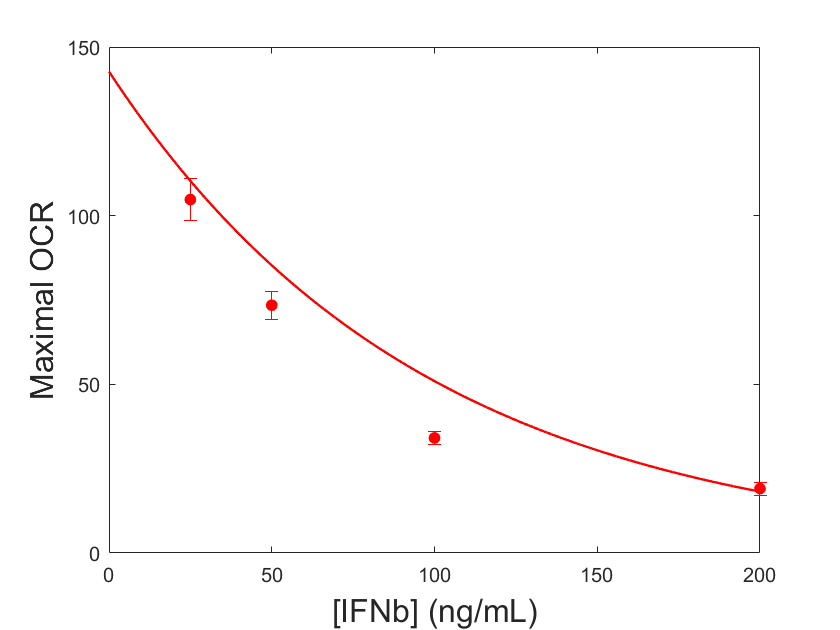



% Plot figure of IFNb
x = 0:0.1:200;
% nexttile;
figure;
% Plot experimental data and the fitted curve
errorbar(data_5.IFNb_ngMl, data_5.IFNb_Mean, data_5.IFNb_SEM,'r.','MarkerSize',20);hold on;
a_IFNb = 142.7297; % R2 = 0.9781
b_IFNb = -0.0103;
plot(x,a_IFNb*exp(b_IFNb.*x),'r','LineWidth',1.2,'HandleVisibility','off'); hold on;
xlabel('[IFNb] (ng/mL)','FontSize',16);
ylabel('Maximal OCR','FontSize',16);
set(gca, 'ylim',[0 150]);
set(gca, 'ytick',[0:50:150]);
saveas(gcf,'plot13b_OCR-IFNb.jpg');

As you can see, there is an exponential increase in OCR with cGAMP treatment and exponential decrease in OCR with IFNb treatment.

## Fitting ODE model to experimental time-course

We want to estimate the parameters of the differential equation $$\frac{dx}{dt} = \beta + \alpha \frac{x^n}{1+x^n} - x$
$. Let's first visualize how it would look like

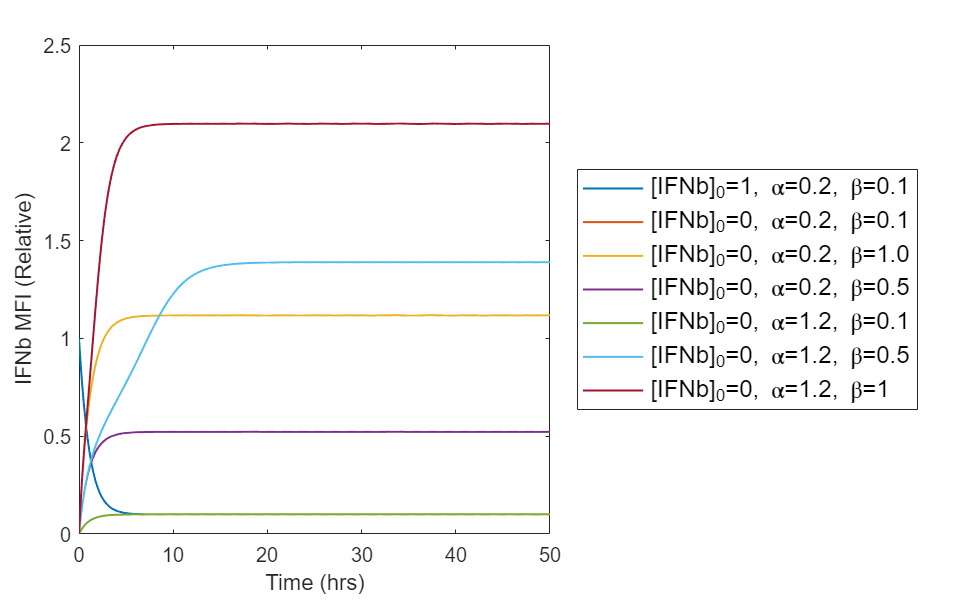

% use the custom-defined kinetics function where n=3.2. Let's test the following parameters
tspan = 0:0.1:50;n=3.2;
x0 = 1;alpha=0.2;beta=0.1; [t,x1] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);
x0 = 0;alpha=0.2;beta=0.1; [t,x2] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);
x0 = 0;alpha=0.2;beta=1; [t,x3] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);
x0 = 0;alpha=0.2;beta=0.5; [t,x4] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);
x0 = 0;alpha=1.2;beta=0.1; [t,x5] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);
x0 = 0;alpha=1.2;beta=0.5; [t,x6] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);
x0 = 0;alpha=1.2;beta=1; [t,x7] = ode45(@(t,x) beta-x+alpha.*x^n/(1+x^n), tspan, x0);

% make plots
f=figure;
x0=10;
y0=10;
width=650;
height=400;
f.Position = [x0 y0 width height];
plot(t, x1,'LineWidth',1); hold on;
plot(t, x2,'LineWidth',1); hold on;
plot(t, x3,'LineWidth',1); hold on;
plot(t, x4,'LineWidth',1); hold on;
plot(t, x5,'LineWidth',1); hold on;
plot(t, x6,'LineWidth',1); hold on;
plot(t, x7,'LineWidth',1); hold on;

Legends={};
Legends{1}='[IFNb]_0=1, \alpha=0.2, \beta=0.1';
Legends{2}='[IFNb]_0=0, \alpha=0.2, \beta=0.1';
Legends{3}='[IFNb]_0=0, \alpha=0.2, \beta=1.0';
Legends{4}='[IFNb]_0=0, \alpha=0.2, \beta=0.5';
Legends{5}='[IFNb]_0=0, \alpha=1.2, \beta=0.1';
Legends{6}='[IFNb]_0=0, \alpha=1.2, \beta=0.5';
Legends{7}='[IFNb]_0=0, \alpha=1.2, \beta=1';
legend(Legends,'Location','eastoutside','FontSize',12)
ylabel('IFNb MFI (Relative)')
xlabel('Time (hrs)')

Now let's see if we have experimental data whether we can fit to the above equation

% Import in experimental data
data_6 = readtable('TM_TimeLapse.csv');

t = data_6.Time_hrs;
c300 = data_6.x300_Mean;
c150 = data_6.x150_Mean;
c75 = data_6.x75_Mean;

theta0=[0.1;1];
[theta1,Rsdnrm,Rsd,ExFlg,OptmInfo,Lmda,Jmat]=lsqcurvefit(@kinetics,theta0,t,c300);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


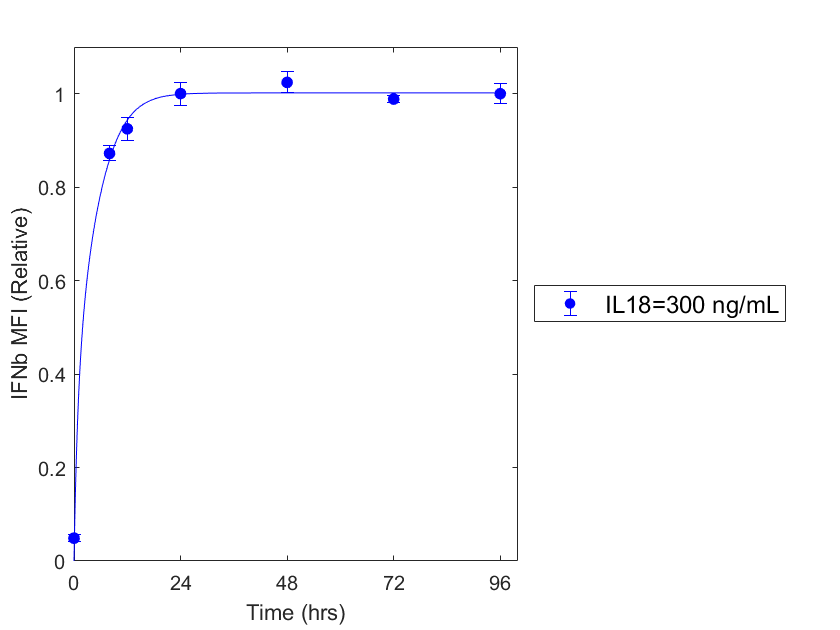

% solve ODEs using fitted theta params
tspan = 0:0.1:96;n=3.2;
x0 = 0;[~,x1] = ode45(@(t,x) theta1(1)-x+theta1(2).*x^n/(1+x^n), tspan, x0);

% make plots
figure;
errorbar(t, c300, data_6.x300_SEM, 'b.','MarkerSize',20); hold on;

plot(tspan, x1,'b'); hold on;

Legends={};
Legends{1}=sprintf('IL18=300 ng/mL');

legend(Legends,'Location','eastoutside','FontSize',12)
ylabel('IFNb MFI (Relative)')
xlabel('Time (hrs)')
set(gca,'xtick',0:24:100);
set(gca, 'ylim',[0 1.1]);
set(gca, 'ytick',[0:0.2:1.0]);
saveas(gcf,'plot14v2_TimeLapse.jpg');

As we can see, the experimental data can be nicely fit to the  differential equation $$\frac{dx}{dt} = \beta + \alpha \frac{x^n}{1+x^n} - x$
$ where $n$ = 3.2 (as we previously determined when fitting the experimental data of sigmoidal activation to the Hill function). Namely, the $\beta$, $\alpha$ value pair is [0.534, 0.932] for 300 ng/mL doses. Most importantly, the BMDMs reach maximal activation within 24 hours of IL-18 stimulation, thus validating that a steady-state is reached by 24 hours.